# Obliczanie całek

Aby mieć dokładne wyniki włączamy pokazywanie większej niż zwykle liczby cyfr znaczących.

format long

Definiujemy funkcję Gaussa


$$f(x, x_0, \sigma) =
\frac 1 {\sqrt {2 \pi} \sigma}
 \exp \bigg[ -\frac {(x-x_0)^2} {2 \sigma^2} \bigg]$$


gauss = @(x, x0, sigma) 1 / sqrt(2*pi) ./ sigma .* exp(- (x-x0).^2 / 2 ./ sigma.^2);

Interesuje nas pole powierzchni w zakresie od -1 do +1

a = -1

a =     -1


b = +1

b =      1


N = 500 % liczba punktów

N =    500


x = linspace(a, b, N);

dla różnych wartości parametru $\sigma$

sigma_values = 1 ./ (0.1 : 0.5: 20.0)

sigma_values =   10.000000000000000   1.666666666666667   0.909090909090909   0.625000000000000   0.476190476190476   0.384615384615385   0.322580645161290   0.277777777777778   0.243902439024390   0.217391304347826   0.196078431372549   0.178571428571429   0.163934426229508   0.151515151515152   0.140845070422535   0.131578947368421   0.123456790123457   0.116279069767442   0.109890109890110   0.104166666666667   0.099009900990099   0.094339622641509   0.090090090090090   0.086206896551724   0.082644628099174   0.079365079365079   0.076335877862595   0.073529411764706   0.070921985815603   0.068493150684932   0.066225165562914   0.064102564102564   0.062111801242236   0.060240963855422   0.058479532163743   0.056818181818182   0.055248618784530   0.053763440860215   0.052356020942408   0.051020408163265


Zobaczmy wykresy i policzmy pole powierzchni

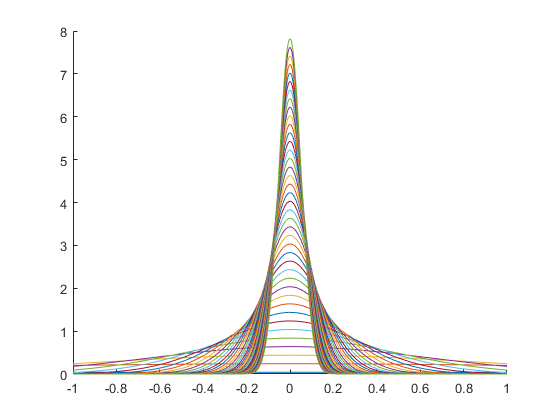

figure(1);
clf;
hold all;

p = [];
q = [];

for sigma = sigma_values
    y = gauss(x, 0, sigma);
    plot(x, y);
    p = [p; trapz(x, y)];
    q = [q; integral(@(x)gauss(x,0,sigma),a,b)];
end

[sigma_values(:), p, q]

ans =   10.000000000000000   0.079655673491271   0.079655674554058
   1.666666666666667   0.451493571792374   0.451493764499853
   0.909090909090909   0.728667101774567   0.728667878107235
   0.625000000000000   0.890400200188431   0.890401416600884
   0.476190476190476   0.964270068299351   0.964271158874367
   0.384615384615385   0.990676984778041   0.990677623952563
   0.322580645161290   0.998064533011956   0.998064793573563
   0.277777777777778   0.999681706386498   0.999681782819685
   0.243902439024390   0.999958668516039   0.999958684986175
   0.217391304347826   0.999995772448120   0.999995775090595


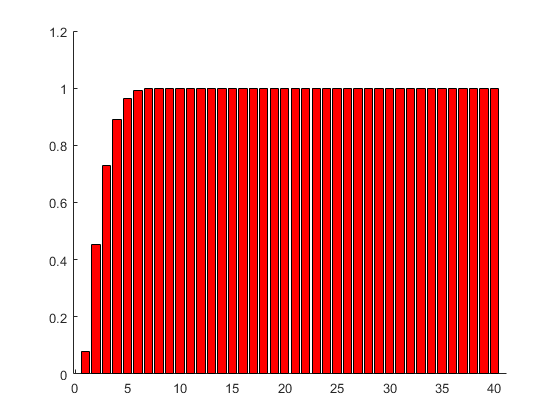

figure(2);
clf;
hold all;
bar(p, 'blue');
bar(q, 'red');